# Read in the RX data

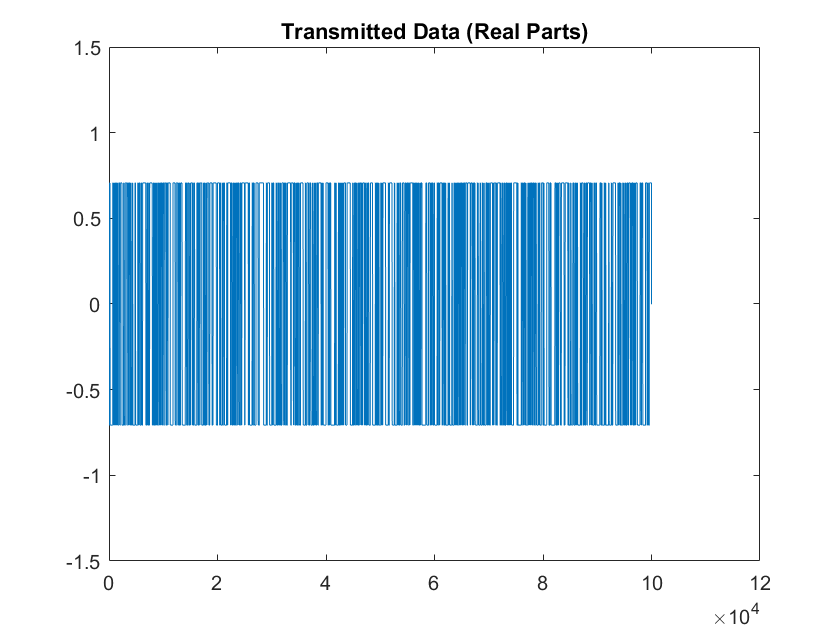

txname='tx_x11.dat';
dat=read_usrp_data_file(txname);
figure
plot(real(dat))
title('Transmitted Data (Real Parts)')
ylim([-1.5,1.5]);

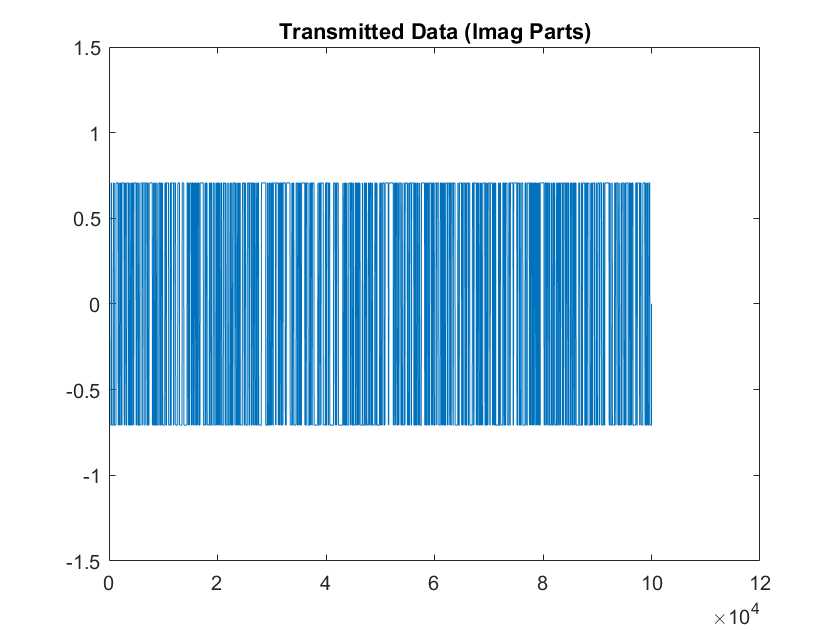

figure
plot(imag(dat))
title('Transmitted Data (Imag Parts)')
ylim([-1.5,1.5]);

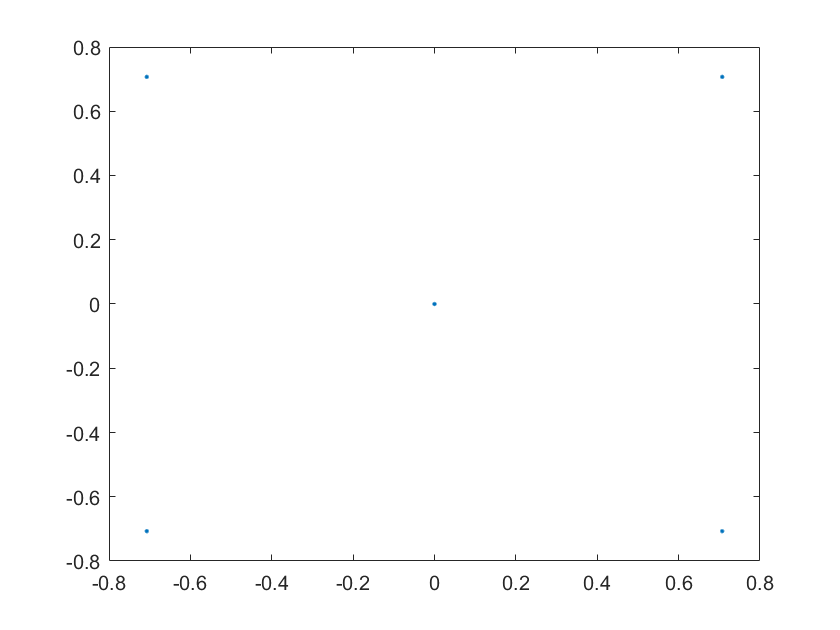

figure
plot(real(dat),imag(dat), '.')

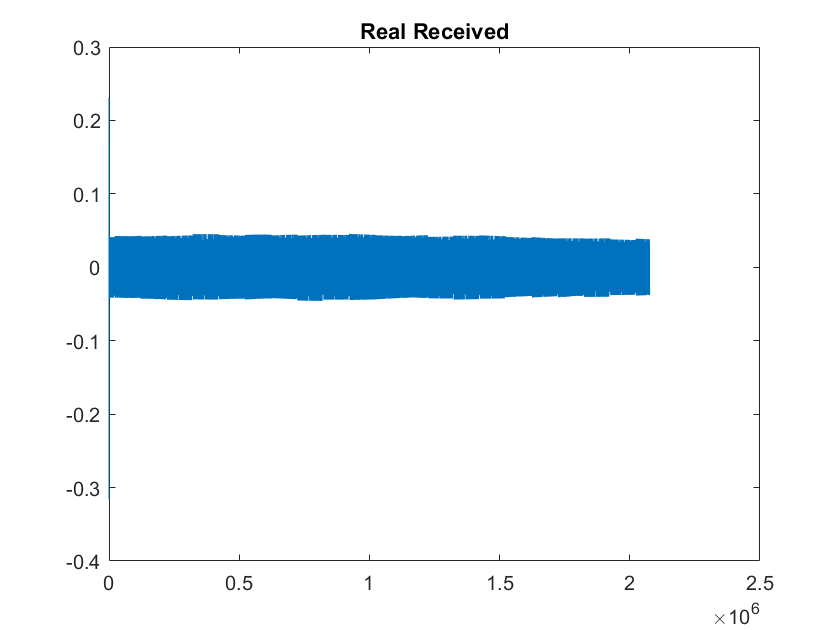

rxname='rx_x11.dat';
read=read_usrp_data_file(rxname);

% Plot the real and imaginery part
figure
plot(real(read))
%ylim([-1.5,1.5]);
title('Real Received')

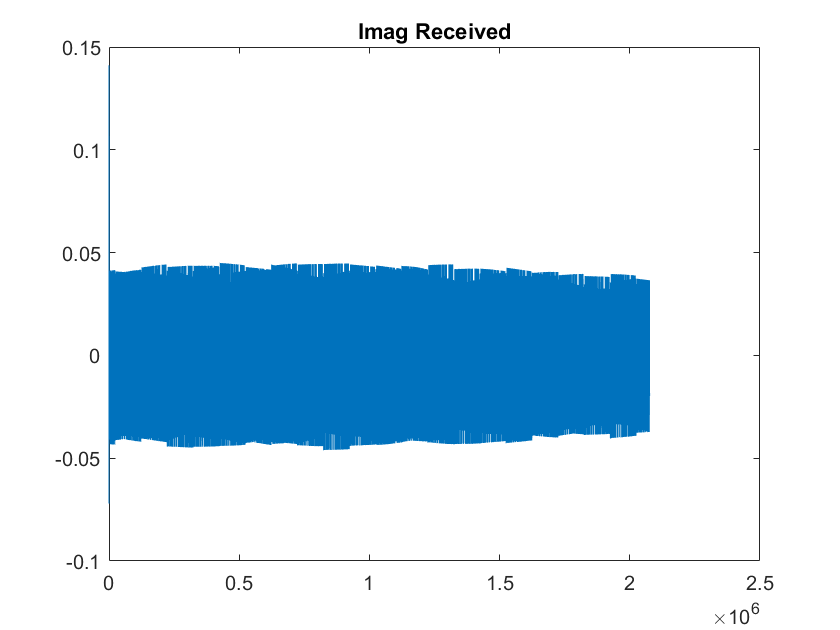

figure
plot(imag(read))
title('Imag Received')

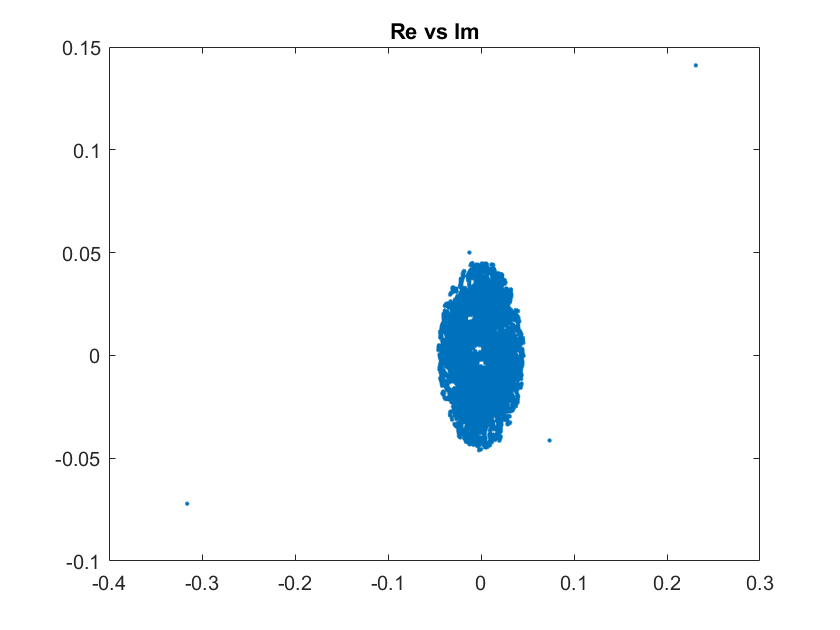


% Plot real vs imaginary
figure
plot(real(read),imag(read),'.')
title('Re vs Im')

## Autocorrelate white noise

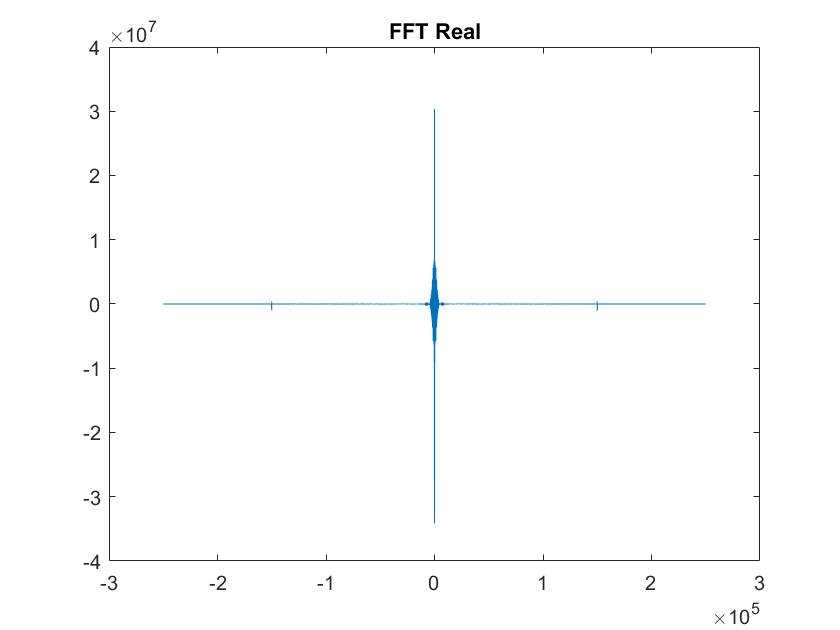

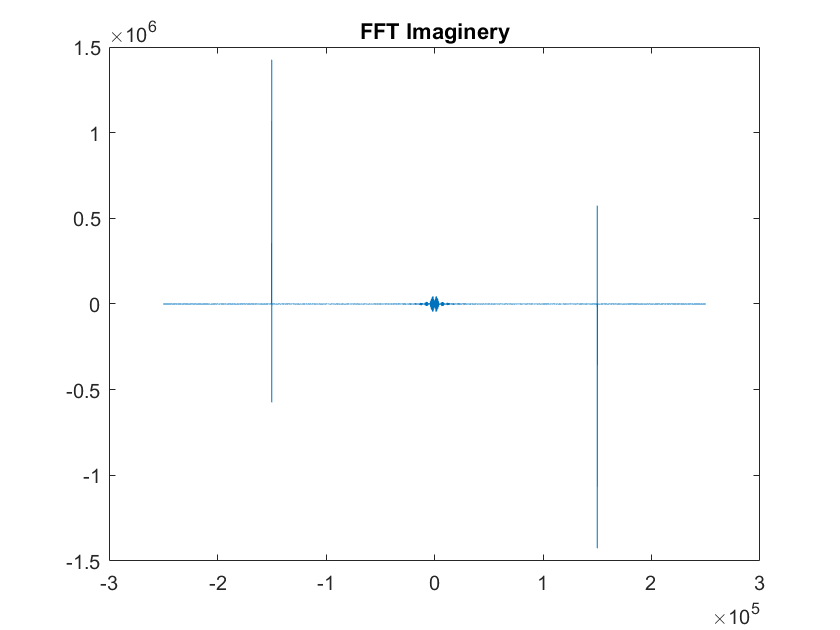

[rauto, lagsauto] = xcorr(real(read), real(read));
plot_FT(rauto, 500000);

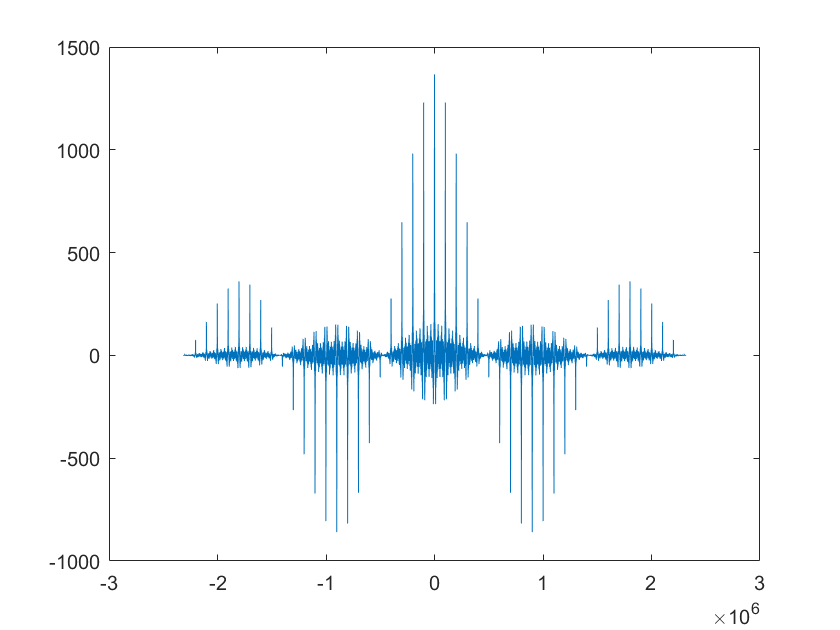

plot(lagsauto,rauto)

## Cross-correlation of the real part

[r, lags]=xcorr(read,dat);
plot(lags,abs(r))
startPos = lags(find(abs(r) == max(abs(r))))

startPos = 223113

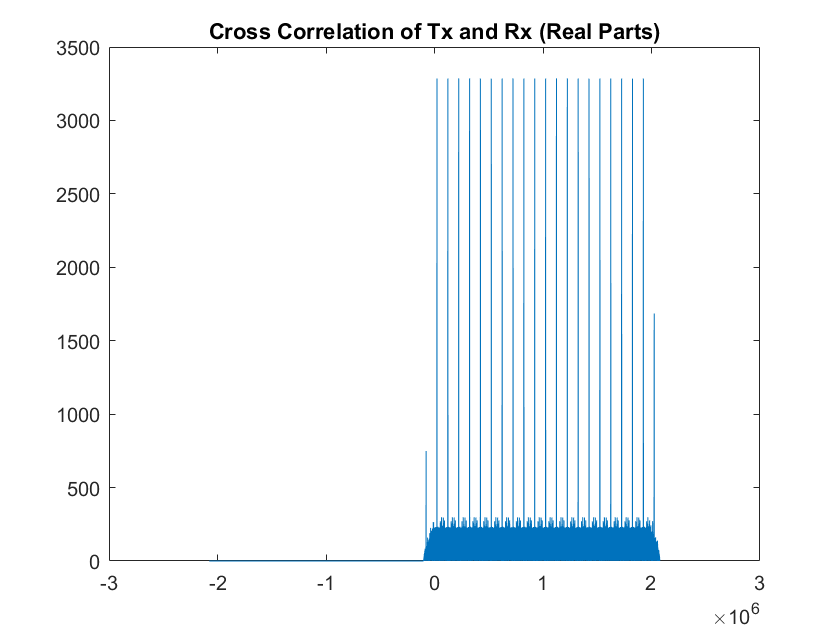

%startPos = 472100
title('Cross Correlation of Tx and Rx (Real Parts)')

% xlim([-10^5 10^5])
% ylim([-.2 .2])

## Cross-correlation of the imaginery part

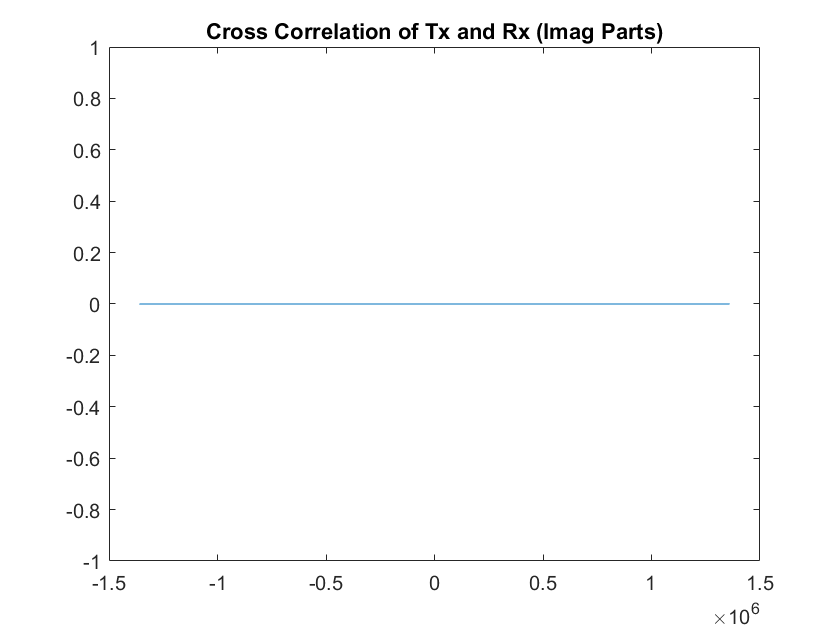

[r, lags]=xcorr(imag(read),imag(dat));
plot(lags,r)
title('Cross Correlation of Tx and Rx (Imag Parts)')

% xlim([-10^5 10^5])
% ylim([-.2 .2])

## Error Rate Calculation

read_shifted=read(startPos+10:end);
%read_ds=downsample(read_shifted,100);
data_ds = downsample(dat,100);
%signal_rx = read_ds(1:length(data_ds));
signal_rx = read_shifted(1:length(dat));
rx_real = sign(real(signal_rx));
rx_im = sign(imag(signal_rx));
rx_tot = rx_real + rx_im;
% signal_ds = zeros(length(downsample(dat,100)),1);
% for curr_pos = 1:100:length(signal_rx)
%     avg = sum(signal_rx(curr_pos:curr_pos+100))/100;
%     %signal_ds((curr_pos+100/100)+1) = avg;
% end
% plot(signal_ds)
signal_rx_up = sign(signal_rx(1))*signal_rx;
signal_rx = downsample(signal_rx_up, 100,50);
%signal_rx_noise = signal_rx + sign(randn(length(signal_rx),1))*0.001;
rx_real = sign(real(signal_rx));
rx_im = sign(imag(signal_rx));
signed_down_real = sign(real(data_ds));
signed_down_im = sign(imag(data_ds));
error_real=rx_real-signed_down_real;
error_imag=rx_im-signed_down_im;
err_real = length(find(error_real~=0));
err_imag = length(find(error_imag~=0));
err_total = err_real + err_imag;
err_rate=err_total/(length(signal_rx)*2);
%error = sign(signal_rx)-sign(data_ds);
%error=sign(real(signal_rx_noise))-real(real(dat));
%error = error_real + error_imag;
%err_num=length(find(error~=0));
%err_rate=err_num/(length(signal_rx));
err_rate

err_rate = 0.5005

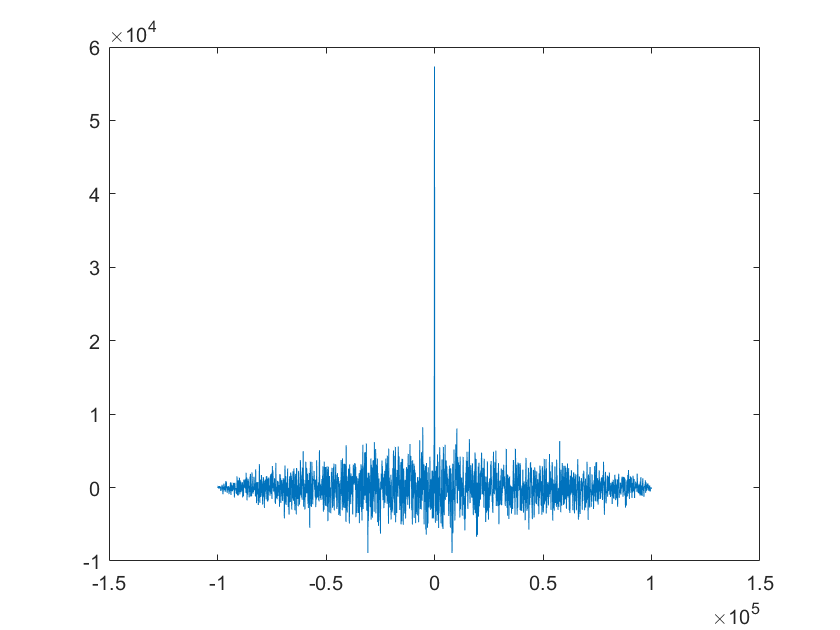

[r, lags]=xcorr(real(rx_tot),real(dat));
plot(lags,r)

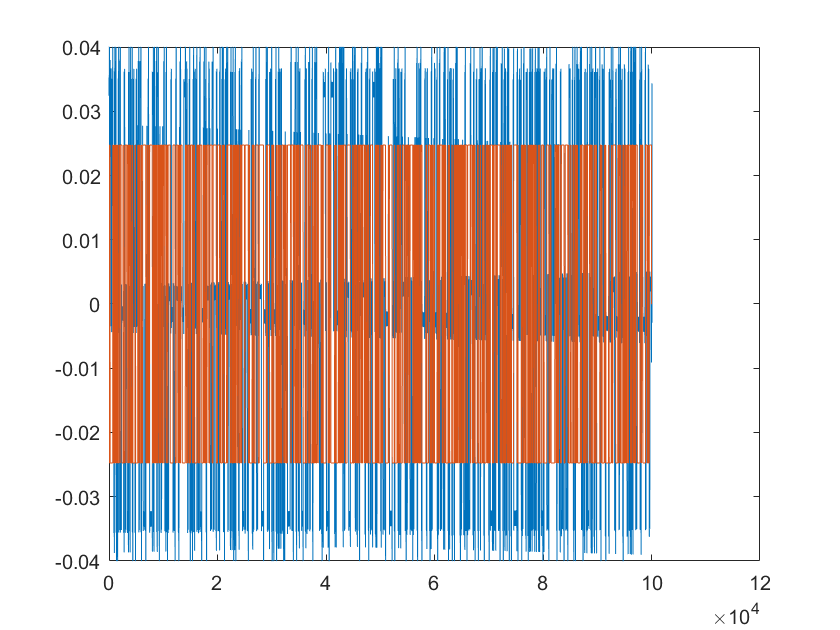

figure
plot(real(signal_rx_up))
ylim([-0.04,0.04])
%xlim([0,2e5])
hold on;
plot(real(dat)*0.035)
hold off;

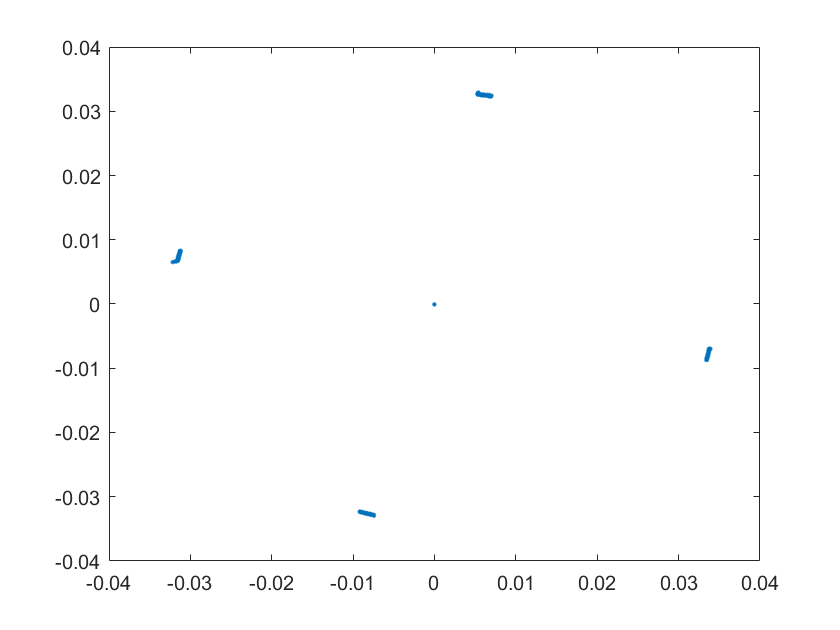

plot(real(signal_rx),imag(signal_rx),'.')

%xlim([-0.04,0.04])

## Attempt to adjust for phase shifting

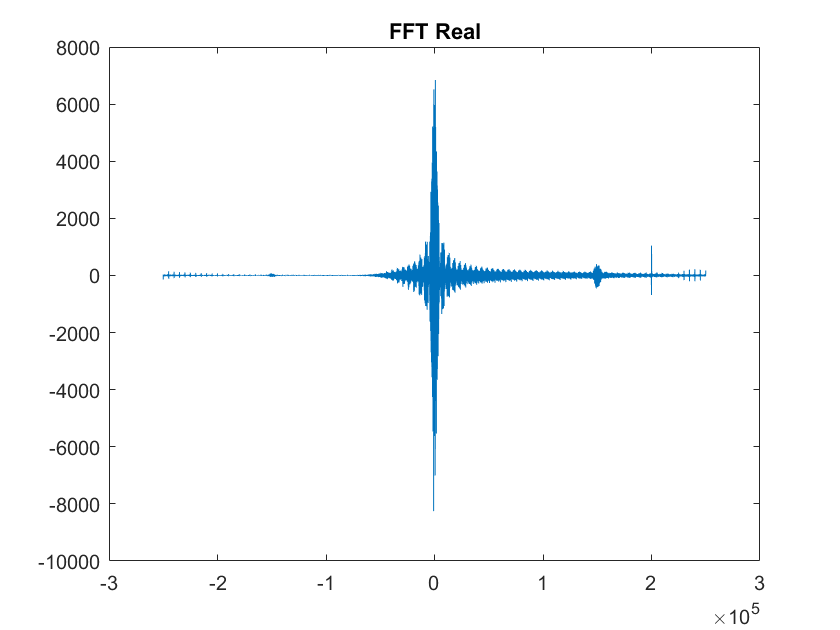

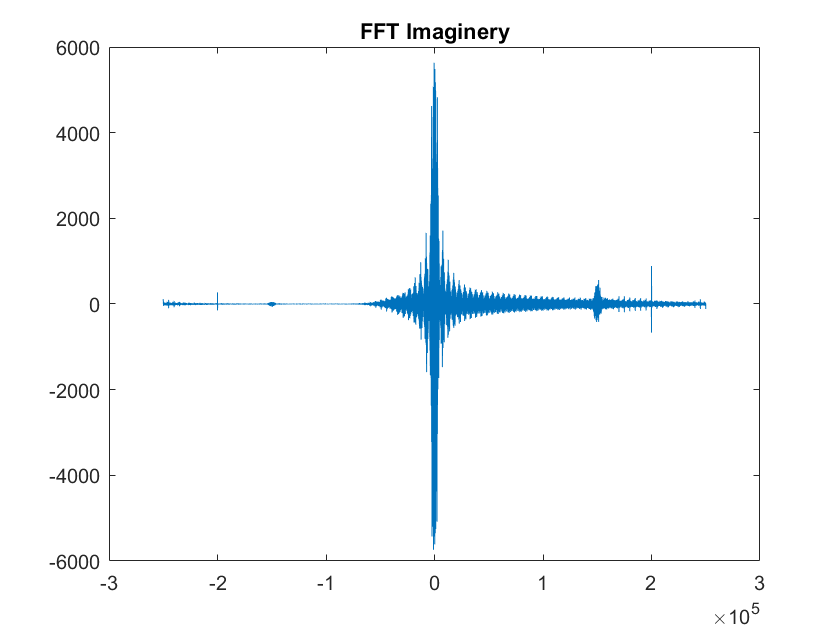

y_norm=signal_rx_up./rms(abs(signal_rx_up));
y_norm_2=y_norm.^2;
plot_FT(y_norm_2, 500000);


% 2f = 200000
% 2phi = arctan(-1422497.7246/-642656);
ff_real = real(fft(y_norm_2));
max_val = max(ff_real)

max_val = 6.8463e+03

ff_real(166)

ans = 6.8463e+03

max_val = find(ff_real==max(ff_real))

max_val = 166

%check = real(y_norm_2(82330))
ff_im = imag(fft(y_norm_2));
phi=atan(ff_im(max_val)/ff_real(max_val))/2

phi = -0.2851

f=0/2;

k=1:length(signal_rx);
offset=exp(-1j*(f*(k-1)*1/500000+phi));
%read_ds=read(153580:153580+length(dat)-1);
% read_ds=downsample(read_ds,20);
read_offset=times(signal_rx,offset');

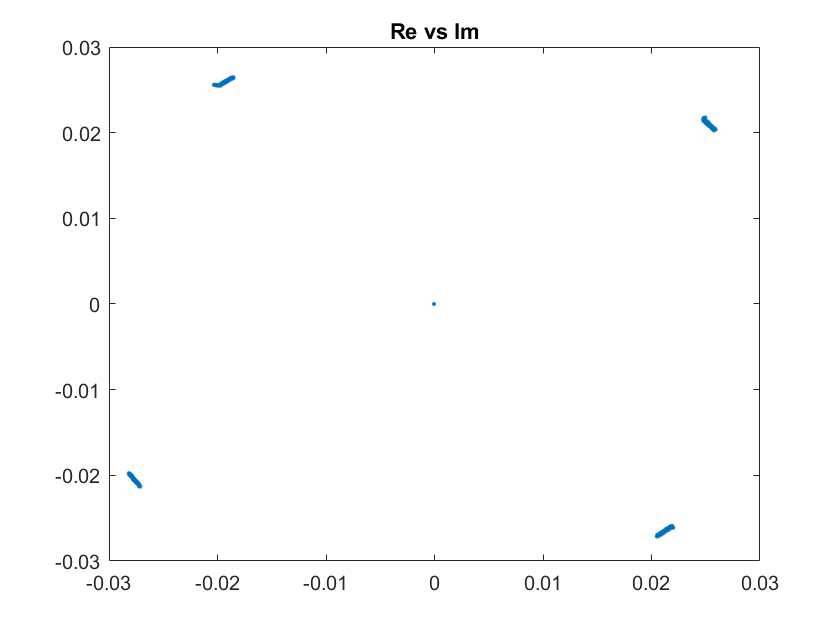


% Plot real vs imaginary
figure
plot(real(read_offset),imag(read_offset),'.')
title('Re vs Im')

error_real=sign(real(read_offset))-sign(real(data_ds));
error_imag=sign(imag(read_offset))-sign(imag(data_ds));
err_real = length(find(error_real~=0));
err_imag = length(find(error_imag~=0));
err_total = err_real + err_imag;
err_rate=err_total/(length(signal_rx)*2);
%error = sign(signal_rx)-sign(data_ds);
%error=sign(real(signal_rx_noise))-real(real(dat));
%error = error_real + error_imag;
%err_num=length(find(error~=0));
%err_rate=err_num/(length(signal_rx));
err_rate

err_rate = 0.5005